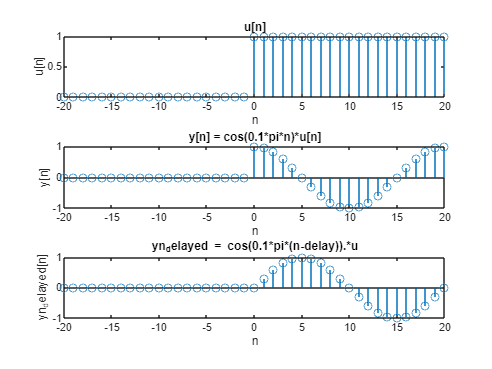

% Given system defined by the equation
% y[n] = cos(0.1*pi*n)*u[n]

% Define the range of n
n = -20:20;

% Define the input signal u[n]
u = zeros(size(n));
u(n>=0) = 1;

% Define the output signal y[n]
y = cos(0.1*pi*n).*u;

% Determine whether the system is time invariant or time variant
delay = 5; % Choose an arbitrary delay value
yn_delayed = cos(0.1*pi*(n-delay)).*u;


% Plot the input signal
subplot(3, 1, 1);
stem(n, u);
title('u[n]');
xlabel('n');
ylabel('u[n]');


% Plot the output signal
subplot(3, 1, 2);
stem(n, y);
title('y[n] = cos(0.1*pi*n)*u[n]');
xlabel('n');
ylabel('y[n]');

% Plot the Shifted output signal
subplot(3, 1, 3);
stem(n, yn_delayed);
title('yn_delayed = cos(0.1*pi*(n-delay)).*u');
xlabel('n');
ylabel('yn_delayed[n]');




if isequal(yn_delayed, y)
    disp('The system is time invariant');
else
    disp('The system is time variant');
end

The system is time variant
